# Archimedes螺旋线方程 & 画图

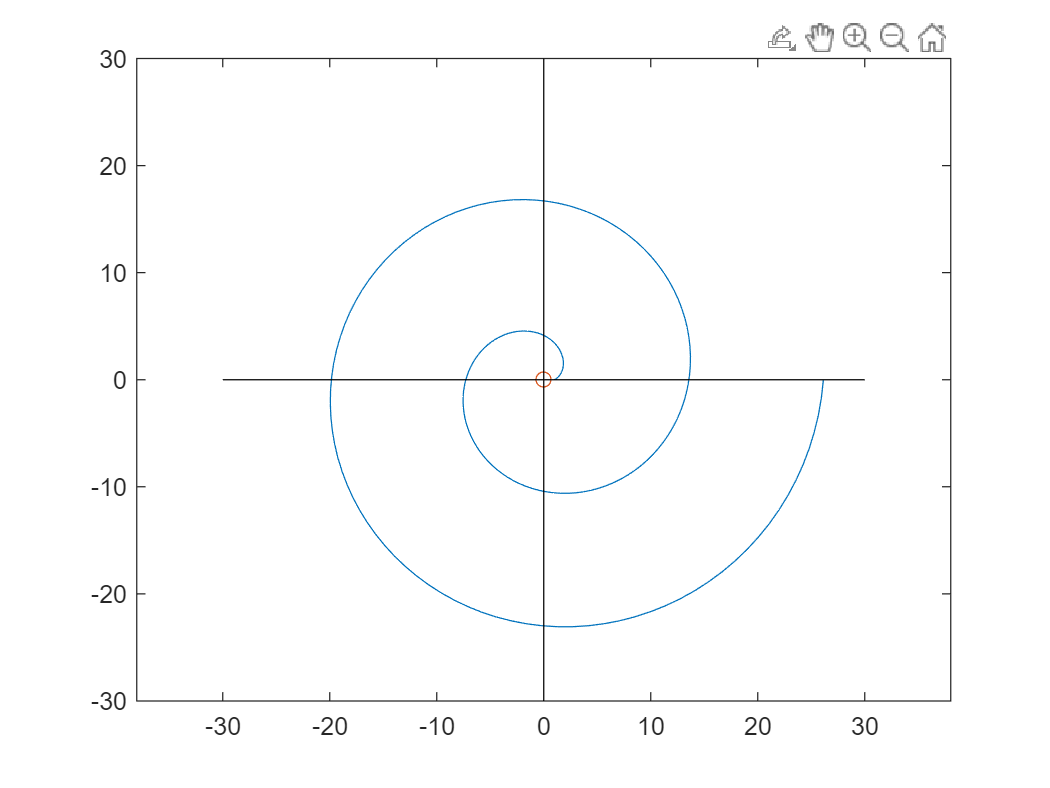


syms theta;
r = @(theta) 1 + 2.*theta;

theta0 = linspace(0,4*pi,200);
r0 = r(theta0);
x0 = r0.*cos(theta0);
y0 = r0.*sin(theta0);

plot(x0,y0); hold on;
scatter(0,0);
line([-30,30],[0,0],'Color','black');
line([0,0],[-30,30],'Color','black');
axis equal

## 螺旋线弧长计算

螺旋线的弧长计算公式为：


$$L=\int_{\theta_{1}}^{\theta_2} \sqrt{\left(r(\theta)\right)^{2}+\left(\frac{dr}{d\theta}\right)^{2}}d\theta$$


rTheta = diff(r,theta);
intFunc = matlabFunction(sqrt(sym(r).^2 + rTheta.^2),'Vars',theta);
L = integral(intFunc,0,4*pi)

L =      1.734537322742454e+02
